# Anden lektion - Frie dæmpede svingninger

clear

syms zeta lambda t A wn k m



eq = A*lambda^2*exp(lambda*t) + 2*zeta*A*wn*lambda*exp(lambda*t) + wn^2*A*exp(lambda*t) == 0



sol = solve(eq, lambda)
simplify(sol)


%%%%


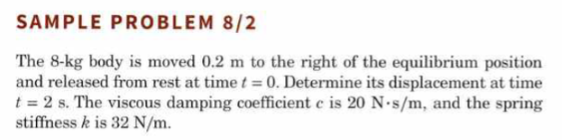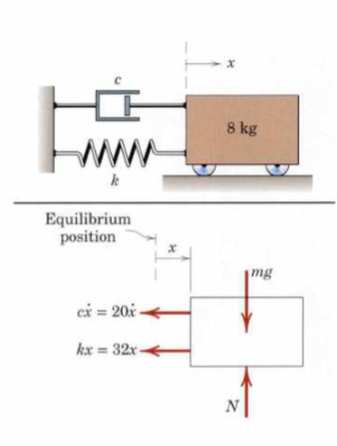

## Underdæmpet da zeta < 1

clear

% Data fra opgaven
m = 8;  x0 = 0.2;   t0 = 0; t1 = 2; Cd = 20; k = 32;

% Formler

wn1 = sqrt(k/m)
zeta1 = Cd/(2*m*wn1)
wd1 = wn1*sqrt(1 - zeta1^2)

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x

x_plac = C*exp(-zeta*wn*t) * sin(wd*t + psi) == x0;
% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3)
% til t1;
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3)
;
x_vel = diff(x_plac, t) == 0;
% til t0;
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3);
% til t1;
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3);


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, psi];

solt0 = solve(eqst0, unks)
solt1 = solve(eqst1, unks)

C = max(solt0.C)
psi = max(solt0.psi(2))

x_plac = vpa(C*exp(-zeta1*wn1*t1) * sin(wd1*t1 + psi),3)

syms func(t)
func(t) = C*exp(-zeta1*wn1*t) * sin(wd1*t + psi)

fplot(func(t), [0,10]), grid()

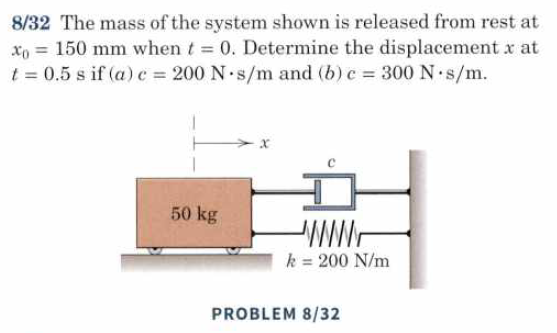

## Kritisk dæmpet da zeta = 1

clear
% Data fra opgaven
m = 50;  
x0 = 0.15; 

t0 = 0; 
t1 = 0.5; 

Cd = 200; 
k = 200;

% Formler

wn1 = sqrt(k/m)
zeta1 = Cd/(2*m*wn1)
wd1 = wn1*sqrt(1 - zeta1^2)

syms A1 A2 t x1

x_plac_t0 = (A1 + A2*t)*exp(-wn1*t) == x0
x_plac_t1 = (A1 + A2*t)*exp(-wn1*t) == x1
x_vel = diff(x_plac_t0, t)


eq1 = x_plac_t0 == x0;
eq2 = x_vel == x1

eqs = [eq1, eq2];
vars = [A1, A2];

sols = solve(eqs, vars);
sols.A1
A1_ny = subs(sols.A1, t, t0)
A2_ny = subs(sols.A2, t, t0)

svar = subs(x_plac_t1, [A1, A2, t], [A1_ny, A2_ny, t1]);
vpa(svar, 4)



## overdæmpet da zeta > 1

clear all
format short
% Data fra opgaven
m = 300;  x0 = -1;   t0 = 0; t1 = 2; Cd = 2*1175; k = 3*900;    v0 = 18;

% Formler

wn = sqrt(k/m)

wn = 3

zeta = Cd/(2*m*wn)

zeta = 1.3056


% Diff ligninger (skal rettes lidt til) - plus conditions

syms A1 A2 t x1

x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x0;

x_vel = diff(x_plac_t0, t) == v0;


eqs = [x_plac_t0, x_vel];
vars = [A1, A2];

% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne sammen
% med t1

sols = solve(eqs, vars);

A1_ny = vpa(subs(sols.A1, t, t0),3)

$$A1\_ny = -1.28$$

A2_ny = vpa(subs(sols.A2, t, t0),3)

$$A2\_ny = 0.278$$


svar = subs(lhs(x_plac_t0 + 1), [A1, A2, t], [A1_ny, A2_ny, t1]);
vpa(svar, 4)

$$ans = 0.9221$$